addpath 'D:\dpl\MATLAB_Sim_and_Analysis'
addpath 'D:\some_fhn_stuff\utils'
warning('off','all')

w = 100;

params.Tau = w;
params.TauR = w;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 10.00;
params.b = 1;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Initial conditions
initCon = [0.2; 0.2];

soma = Dendrite(0, paramsSoma, initCon);
dendrite = Dendrite(0, params, initCon);

% dendritic tree model
tree = DendriteTreeModel();

% Add soma
tree.addDendrite(soma);

[ab, bb, cb] = ButcherTableau.get("RK4");
solver = rk_solver(ab, bb, cb); %RK4

tmax = 1;
h = 1/(64e+3);

t = 0 : h : tmax;

A = 1;
F = 10;
sig = A * sin(2 * pi * F * t);

fhn = @(t, y) FHN_EXT(t, y, w, params.alpha, params.b, sig, h);

tic
[t_ode, sol_ode] = solver.solve(fhn, tmax, initCon, h);
toc

Elapsed time is 5.739162 seconds.



tree.addStimuli(0, sig);

tic
[t_mex, sol_mex] = treeSolver(tree, tmax, h);
toc

Elapsed time is 0.092277 seconds.



opts = odeset(MaxStep=h*4);
tic
[t_base, sol_base] = ode45(fhn, [0; tmax], initCon, opts);
toc

Elapsed time is 1.343697 seconds.



sol_base = sol_base';

sprintf("RMSE old/mex = %d", rmse(sol_ode(1, :), sol_mex(1, :)))

ans = "RMSE old/mex = 1.147584e-03"

sprintf("RMSE ode45/mex = %d", rmse(sol_base(1, :), sol_mex(1, :)))

ans = "RMSE ode45/mex = 1.147584e-03"

sprintf("RMSE ode45/old = %d", rmse(sol_base(1, :), sol_ode(1, :)))

ans = "RMSE ode45/old = 7.637291e-09"

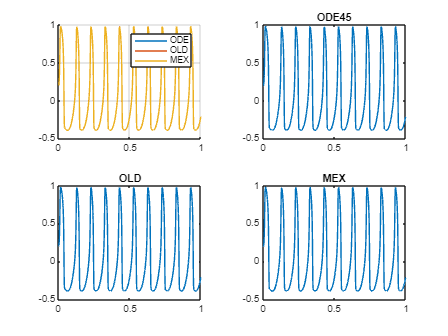


figure
tiledlayout(2, 2)
nexttile
hold on
plot(t_base', sol_base(1, :));
plot(t_ode, sol_ode(1, :));
plot(t_mex, sol_mex(1, :));
legend("ODE", "OLD", "MEX")
grid on

nexttile
plot(t_base', sol_base(1, :));
title("ODE45")
nexttile
plot(t_ode, sol_ode(1, :));
title("OLD")
nexttile
plot(t_mex, sol_mex(1, :));
title("MEX")




function Ydot = FHN_EXT(t, y, w, alpha, b, EXT, h)
    Ydot = zeros(2,1);
    x = y(1); y = y(2);
    I0 = interp_point_by_point(EXT, t, h); %interpolates external force to exact point of integration
    Ydot(1) = w * (x*(x - 1)*(1 - alpha*x) - y + I0);
    Ydot(2) = w * b*x;
end
